syms t;
t=-1:1/600:1;
    m2=sinc(10*t).*(heaviside(t)-heaviside(t-1))+heaviside(-t)*0;
    AC=1;
    FC=100;
    Ac=1;
    f=1;
    y=@(AC,m2,FC,Ac)((2*(AC.*m2).*cos(2*pi*FC*t).*Ac.*cos(2*f*t*pi)))

y = function_handle with value:
    @(AC,m2,FC,Ac)((2*(AC.*m2).*cos(2*pi*FC*t).*Ac.*cos(2*f*t*pi)))


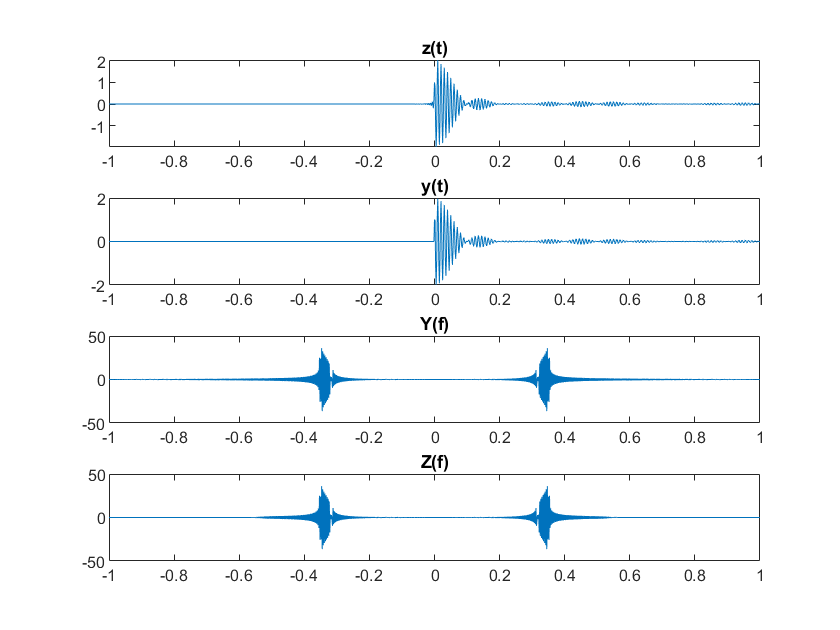

   yt=y(AC,m2,FC,Ac);
   zt=lowpass(yt,0.5);
   ztf=fftshift(fft(zt));
   ytf=fftshift(fft(yt));
   subplot(411),plot(t,zt),title("z(t)")
   subplot(412),plot(t,yt),title("y(t)")
   subplot(413),plot(t,real(ytf)),title("Y(f)")
   subplot(414),plot(t,real(ztf)),title("Z(f)")